% Import data from text file
data = readtable("M:\Documents\MATLAB\csv_files\SDS00008.csv");

% Display results
data

data = 70000×3 table
    Source     CH1     CH2 
    ______    _____    ____

        0     -0.04    0.02
    0.001     -0.04    0.04
    0.002     -0.06    0.06
    0.003     -0.06     0.1
    0.004      -0.1    0.14
    0.005     -0.12    0.14
    0.006     -0.08    0.18
    0.007      -0.1    0.16
    0.008      -0.1    0.16
    0.009      -0.1    0.14
     0.01      -0.1    0.12
    0.011      -0.1     0.1
    0.012      -0.1    0.06
    0.013      -0.1    0.06
    0.014     -0.08    0.02
    0.015     -0.06       0


% Extract columns from the table
time = data.Source; % Assuming 'Source' is the time column
channel1 = data.CH1; % Assuming 'CH1' is the first signal
channel2 = data.CH2; % Assuming 'CH2' is the second signal

% Plot the data
figure;
plot(time, channel1, 'r', 'DisplayName', 'Channel 1'); % Plot CH1 in red

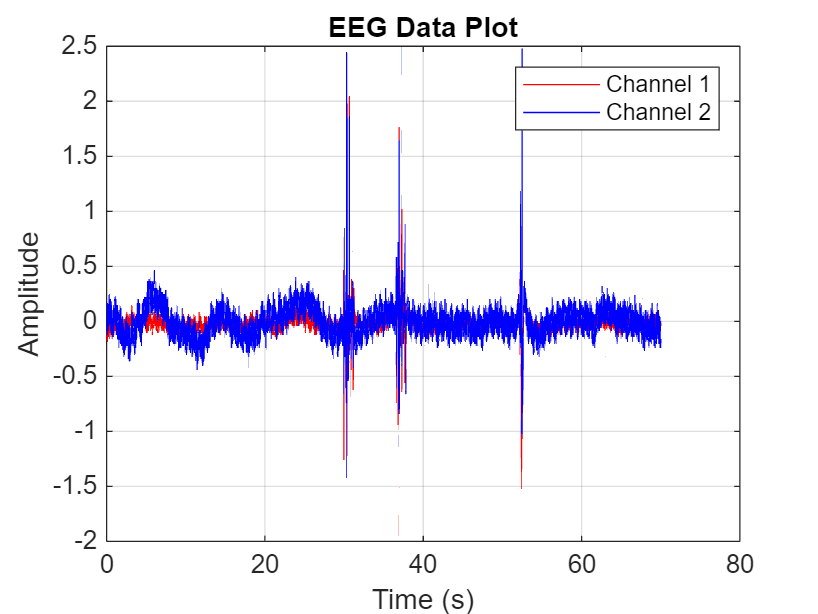

hold on; % Allow multiple plots on the same figure
plot(time, channel2, 'b', 'DisplayName', 'Channel 2'); % Plot CH2 in blue
hold off;

% Add labels and legend
xlabel('Time (s)');
ylabel('Amplitude');
title('EEG Data Plot');
legend show;
grid on;

% Combine data (example: averaging)
combined_data = (channel1 + channel2) / 2;

% Define filter parameters
fs = 1000; % Sampling frequency (adjust to your data's sampling rate)
cutoff_freq = 50; % Cutoff frequency in Hz
[b, a] = butter(4, cutoff_freq / (fs / 2), 'low'); % 4th-order low-pass filter

% Apply the filter
filtered_data = filtfilt(b, a, combined_data); % Zero-phase filtering

% Define filter parameters
fs = 1000; % Sampling frequency (adjust to your data's sampling rate)
cutoff_freq = 50; % Cutoff frequency in Hz
[b, a] = butter(4, cutoff_freq / (fs / 2), 'low'); % 4th-order low-pass filter

% Apply the filter
filtered_data = filtfilt(b, a, combined_data); % Zero-phase filtering

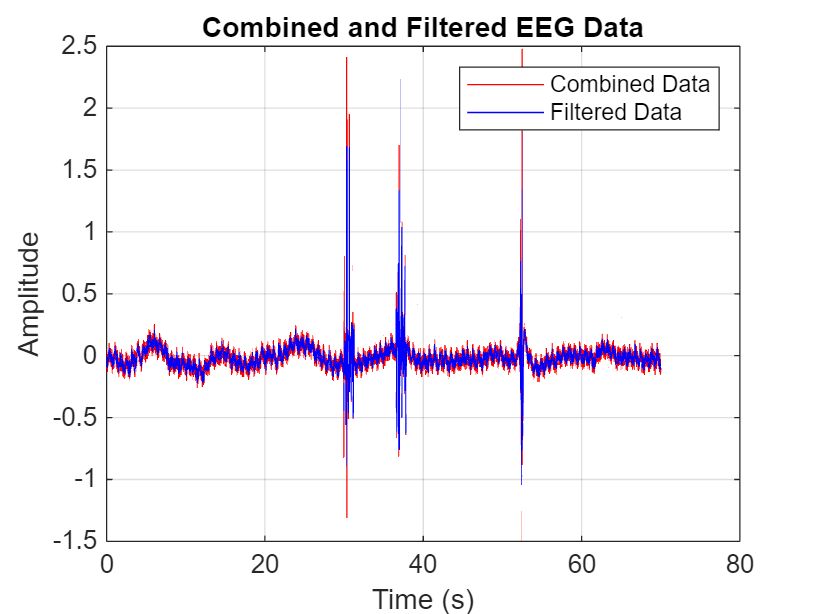

% Plot the original and filtered data
figure;
plot(time, combined_data, 'r', 'DisplayName', 'Combined Data');
hold on;
plot(time, filtered_data, 'b', 'DisplayName', 'Filtered Data');
hold off;

% Add labels and legend
xlabel('Time (s)');
ylabel('Amplitude');
title('Combined and Filtered EEG Data');
legend show;
grid on;